# 基于H∞鲁棒控制的主动降噪耳罩

## 理论背景

### A. H∞鲁棒控制理论

本节简要回顾了H∞鲁棒控制理论。以下推导包含了大量的数学定义和结果。由于H∞理论在大量控制文献中均有详细论述[7-12]，因此这里只列出在ANC算法开发中所需的关键内容，其余部分不再赘述。由于系统模型是通过离散时间域的参数辨识方法获得的，本文仅介绍离散时间H∞算法。

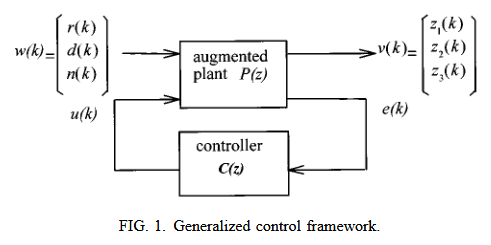

在现代控制理论中，所有控制结构都可以通过广义控制框架来描述，如图1所示。该框架包含一个控制器C(z)和一个增广对象P(z)。受控变量v(k)对应于各种控制目标z₁(k)、z₂(k)、z₃(k)，而外部输入w(k)包括参考信号r(k)、扰动d(k)和噪声n(k)。信号u(k)和e(k)分别为施加到对象的控制输入和从对象测得的输出。

一般的输入-输出关系可表示为：


$$\left\lbrack \begin{array}{c}
V\left(z\right)\\
E\left(z\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
P_{11} \left(z\right) & P_{12} \left(z\right)\\
P_{21} \left(z\right) & P_{22} \left(z\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
W\left(z\right)\\
U\left(z\right)
\end{array}\right\rbrack =P_{\gamma \;} \left(z\right)\left\lbrack \begin{array}{c}
W\left(z\right)\\
U\left(z\right)
\end{array}\right\rbrack$$


其中，子矩阵$P_{\textrm{ij}} \left(z\right),i,j=1,2$是增广对象$P_{\gamma \;} \left(z\right)$的兼容分块（compatible partitions），符号均为Z变换后的变量。H∞控制的基本思想是最小化传递函数$T_{\textrm{vw}} \left(z\right)$（v(k)与w(k)之间）的无穷范数，它可通过线性分式变换（LFT）表示为：


$$T_{vw}(z) = \mathrm{LFT}(P_\gamma(z), C(z)) = P_{11}(z) + P_{12}(z)C(z)[I - P_{22}(z)C(z)]^{-1}P_{21}(z) $$


因此，最优H∞问题的数学表述为：


$$\min_{C(z)} \|T_{vw}(z)\|\infty = \min_{C(z)} \sup_{0 \leq \theta < 2\pi} \|T_{vw}(e^{j\theta})\|$$


然而，寻找最优解通常非常困难，因此实际中常采用可解析获得的次优解。这就形成了所谓的标准H∞问题：寻找C(z)，使得$\|T_{\textrm{vw}} \left(z\right){\|}_{\infty \;} <1$。由于控制问题被纳入广义框架，许多H∞算法都可以综合出最优控制器。

现有算法大致分为两类：**模型匹配算法（Model Matching Algorithms, 1984年方法）**和**两Riccati方程算法（Two-Riccati Equation Algorithms, 1988年方法）**。本研究采用后者，该方法无需像前者那样进行一系列因式分解，因此在处理高阶（声学）对象时可减少数值问题。由于该算法包含大量标准控制文献中的代数定义和表达式，本文不再赘述，详情可参考文献12。

### B 模型匹配方法（1984 Approach）

1980s初，Doyle等人首次把 H∞ 控制问题形式化。Zames、Helton 等早期工作将鲁棒/灵敏度最小化（H∞）问题表述为频域的最坏增益最小化问题。1980s 早期的解法以 **传递函数与因子分解** 为主，目标是找一个控制器 $K\left(s\right)$ 使闭环某个传递矩阵 $T_{\textrm{zw}} \left(s\right)$ 在 H∞ 范数意义下最小（或小于某阈 γ）。该方法常被称作 *model-matching* 或 *factorization-based H∞ method。*

1984 年的早期算法以"模型匹配 (model matching)"为核心。其基本思想是，把H∞ 优化问题转化为一个 **有理函数的逼近问题**，即要求找到一个控制器，使得某个传递函数尽量接近给定的目标函数。它依赖 **一连串的因子分解（chain of factorizations）** 和算子理论工具（如 Nehari 定理、Glover-Millman 类型逼近理论等）。它提供了 H∞ 问题的最早完整解法框架。

- 优点：为 H∞ 理论奠定频域与算子理论基础；在某些解析场景下能给出明确的逼近解。

- 缺点：对高阶系统/噪声很容易出现数值问题；实现复杂；不如状态空间方法在工程上易用。

### C 两Riccati方程方法（1988 Approach）

1988/1989 年 Doyle、Glover、Khargonekar、Francis（DGKF）等把 H∞ 问题带入**状态空间，**给出"标准 H∞ 问题"的**状态空间充分必要条件**：控制器存在当且仅当两个分别与控制方向和估计方向相关的代数 Riccati 方程存在稳定的解，且两解的某个谱半径条件满足。其基本思想是，把 H∞ 控制问题转化为 **两个耦合代数 Riccati 方程 (AREs)** 的解。在给定广义被控系统$P$的情况下，通过求解两个Riccati方程（一个用于控制方向，另一个用于估计方向），构造出满足H∞ 性能指标的控制器。它不需要复杂的因子分解，而是直接在状态空间内计算。**白明宪所选用的方法正是1988方法，因为它不需要像前者那样进行一连串因子分解，因此在处理高阶声学系统时能避免数值问题。**

以连续时间状态空间形式为例：


$$\dot{x}=Ax+B_1w+B_2u\\
z=C_1x+D_{11}w+D_{12}u\\
y=C_2x+D_{21}w+D_{22}u$$


**目标**：求一个动态控制器（状态空间形式）使闭环从 w 到 z 的传递矩阵的 H∞ 范数小于 γ。**DGKF 将问题转化为求解两条代数 Riccati 方程（ARE）**，并给出构造控制器的明确代数表达式；存在性等价于这两 ARE 的 stabilizing 解存在且满足额外的谱半径条件。

- 优点：状态空间形式、可数值实现、对高阶系统较稳定、容易与现代数值代数库结合，成为 MathWorks 等工具箱实现的基础。

- 缺点：需要可控/可观/正则性等假设；构造出的控制器阶次等于植物阶次（可能较高），但可采用降阶或固定结构调优方法（见后）。

### D 标准问题定义

记$P_1 \left(z\right)$为噪声主通路，$P_2 \left(z\right)$为次通路（被控对象），我们设计 H∞ 控制器的方法是对分别对灵敏度函数$\tilde{S} \left(z\right)$，控制输入$U\left(z\right)$，互补灵敏度函数$\tilde{T} \left(z\right)$分别使用$W_1 \left(z\right),W_2 \left(z\right),W_3 \left(z\right)$加权。

一方面，干扰抑制/跟踪性能的标称性能条件（nominal performance condition）要求${\left\|\tilde{S} \left(z\right)W_1 \left(z\right)\right\|}_{\infty \;} <1$；而应对系统干扰（system stability）和模型不确定性（model uncertainties）的系统稳定性，由小增益定理要求${\left\|\tilde{T} \left(z\right)W_3 \left(z\right)\right\|}_{\infty \;} <1$。

在通常的回路成型设计中，$W_1 \left(z\right)$通常被选为低通函数而$W_3 \left(z\right)$被选为高通函数。$S\left(z\right)$与$T\left(z\right)$之间的权衡，以及水床效应共同决定了反馈设计的性能以及鲁棒性。这种经典的权衡就产生了所谓的混合灵敏度（mixed sensitivity problem）问题，它也是控制器同时实现标称性能和鲁棒稳定性的充要条件。

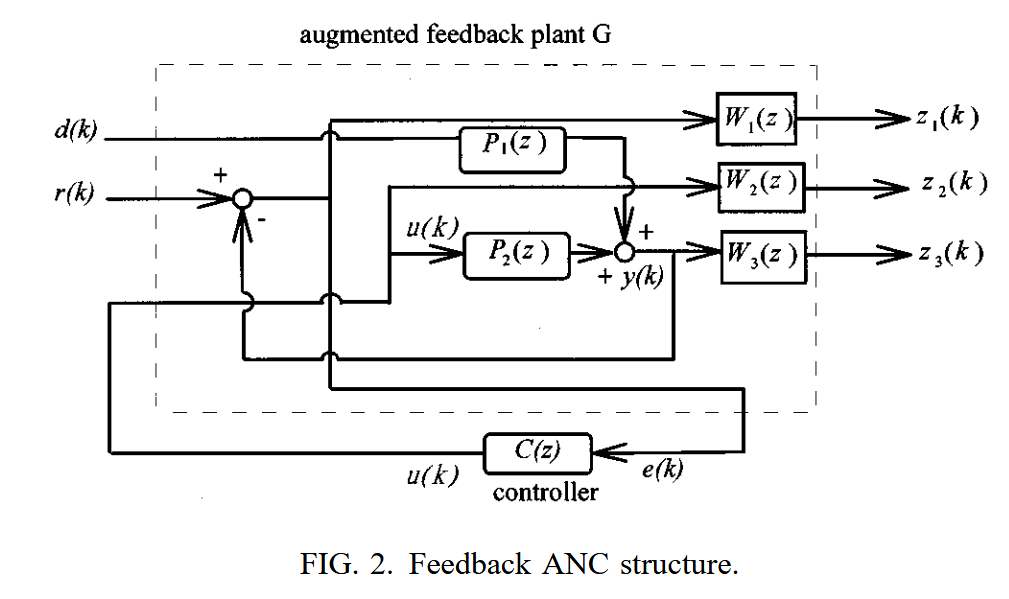

在H∞ 理论里，混合灵敏度问题就是要求：${\left\|\left\lbrack \begin{array}{c}
W_1 S\\
W_2 R\\
W_3 T
\end{array}\right\rbrack \right\|}_{\infty \;} <1$，其中$W_1$为低频性能权重，$W_2$为控制权重，而$W_3$则为高频鲁棒性权重，$R=S\;C$对应控制输入。这在ANC问题中分别对应于噪声抑制、控制信号约束以及闭环稳定裕度这三个目标。ANC 的物理需求和混合灵敏度问题的数学结构是 **一一对应** 的。

文章给出了增广系统的构造：$\left\lbrack \begin{array}{c}
Z_1 \left(z\right)\\
Z_2 \left(z\right)\\
Z_3 \left(z\right)\\
E\left(z\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
W_1 \left(z\right) & -W_1 \left(z\right)P_2 \left(z\right)\\
0 & W_2 \left(z\right)\\
0 & W_3 \left(z\right)P_2 \left(z\right)\\
1 & -P_2 \left(z\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
D\left(z\right)\\
U\left(z\right)
\end{array}\right\rbrack$,其中$D\left(z\right)$是外部扰动，$U\left(z\right)$是控制输入，$E\left(z\right)$是可测输出（麦克风信号）；$Z_1 \left(z\right),Z_2 \left(z\right),Z_3 \left(z\right)$是性能输出的不同构成（对应于加权的灵敏度、控制输入与互补灵敏度），通过引入权重W1, W2, W3，ANC问题（本质是混合灵敏度问题）被改写为一个 **标准 H∞ 控制问题**。

## 1 根据表格参数构建被控对象

clear; close all; clc;
% 1. 构建被控对象的传递函数
z = [-3.0841, 1.0320, -0.4387, 0.0034];
p = [0.6612+0.3483i, 0.6612-0.3483i, -0.4426+0.3324i, -0.4426-0.3324i];
k = 0.3921;
P_tf = zpk(z, p, k);

% 2. 转换为状态空间模型
P = ss(P_tf);
S0 = feedback(1, P_tf);      % S = 1/(1+P*0) = 1
T0 = feedback(P_tf, 1);      % T = P/(1+P*0) = P

## 2 构建加权函数设计H∞控制器

H∞设计需要性能权重（如W1、W2、W3），可以根据实际需求设定。

根据文中图像逆向工程的结果为：


$$W_1^{-1}(s) =\frac{2.37 s^2 + 2500 s + 1.027e7}{  s^2 + 7969 s + 8.542e6}\\
W_3^{-1}(s)=\frac{0.6554 s + 2592}{s + 3266}\\
S(s)=\frac{ 1.265 s^2 + 1380 s + 5.707e6}{s^2 + 4267 s + 8.01e6}\\
T(s)=\frac{0.3975 s^2 + 3218 s + 1.659e6}{s^2 + 4439 s + 7.506e6}$$


% 3. 构建权重函数（示例）
s = tf('s');
W1 = 10/(s/100+1);
W2 = 0.1;
W3 = (s/1000+1)/10;

W1 = ss(W1);
W2 = ss(W2);
W3 = ss(W3);

% 4. 构建加权混合系统（以标准2-DOF H∞结构为例）
systemnames = 'P W1 W2 W3';
inputvar = '[r; u]';
outputvar = '[W1; W2; W3]';
input_to_P = '[u]';
input_to_W1 = '[P-u]';
input_to_W2 = '[u]';
input_to_W3 = '[P]';
sys_ic = P;

% 5. H∞控制器设计
nmeas = 1;
ncon = 1;
[K, CL, gamma] = hinfsyn(sys_ic, nmeas, ncon);

% 6. 查看控制器
C_ss = minreal(K);
C_tf = tf(C_ss);

% 设计后（有控制器）
S1 = feedback(1, P_tf*C_tf);    % S = 1/(1+P*C)
T1 = feedback(P_tf*C_tf, 1);    % T = P*C/(1+P*C)

% 频率范围
w = logspace(1, 4, 1000); % 10~10000 Hz


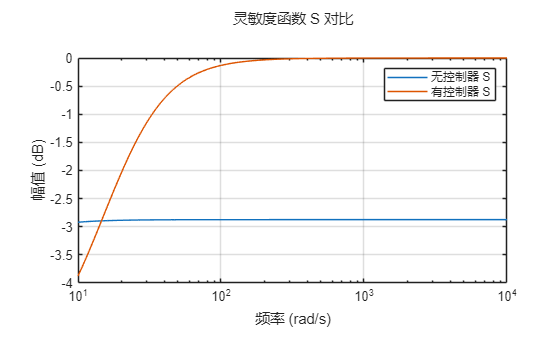

%% 幅频响应对比
figure;
bodemag(S0, S1, w);
legend('无控制器 S','有控制器 S');
title('灵敏度函数 S 对比');
grid on;